# Offline Classification From Features

Neurotechnology, Brains and Machines 2023 (shell code my Sam Michalka)

This shell code expects that you have:

-  data with features already extracted in a variable called feature_table

- labels for the data in a variable called labels. 

The features should be in a table with the rows equal to the number of trials and the columns equal to the number of features. You can select a subset of features in the code below.

% clear
addpath('analysis');
addpath('dataCollection');

Indicate if your test data is in a separate file or partitioned from the train data.

Make a list of files to load. If this has two things, the code will assume it is the train features followed by the test features. If it has one item, it will assume they are training featues and run a train-test split.  

If you want to use resubstitution, put the same training data twice (once as train, once as test).

% filesToLoad = {"features.mat"}; % you'll need to change this name

% filesToLoad = {"latest_feature_table.mat","latest_feature_table.mat"}; % Resubstitution

filesToLoad = {"train_feature_table.mat", "test_feature_table.mat"};    % Train/Test Split

% filesToLoad = {"train_feature.mat", "test_feature.mat"} % Last 300 only



#### Select which features you want. selected_features is the indices of these features. You can get fancy and use contains() if you want to pull them out by name.

% temporarily load the feature data to get selected features
load(filesToLoad{1})                                                                                                                                                                                                                                                                                            

Print out all the feature names

feature_table.Properties.VariableNames

ans = 1×28 cell array
    {'var_Ch1'}    {'var_Ch2'}    {'var_Ch3'}    {'var_Ch4'}    {'mad_Ch1'}    {'mad_Ch2'}    {'mad_Ch3'}    {'mad_Ch4'}    {'rms_Ch1'}    {'rms_Ch2'}    {'rms_Ch3'}    {'rms_Ch4'}    {'std_Ch1'}    {'std_Ch2'}    {'std_Ch3'}    {'std_Ch4'}    {'meanf_Ch1'}    {'meanf_Ch2'}    {'meanf_Ch3'}    {'meanf_Ch4'}    {'medf_Ch1'}    {'medf_Ch2'}    {'medf_Ch3'}    {'medf_Ch4'}    {'i_emg_Ch1'}    {'i_emg_Ch2'}    {'i_emg_Ch3'}    {'i_emg_Ch4'}


Select a subset of features (or all of them)

selected_features = 1:size(feature_table,2) % This selects all features

selected_features =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28


The best combination of selected features is: MAD, RMS, STD, meanf

% selected_features = [5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20] %This selects the first two features listed above

clearvars feature_table labels  % you just temporarily loaded these in to
%get the feature names, delete them so you don't get confused

## Load the feature data and put into X and y matrices

Look inside the function below to set things like train-test split.

[X_train, y_train, X_test, y_test] = featuresTo_X_y_train_test(filesToLoad, selected_features);


## Build a classifier and do k-fold cross-validation

% Perform cross-validation
KFolds = 5;
cvp_kfold = cvpartition(y_train, 'KFold', KFolds);

% Make empty vector to store predictions from k-fold cross-validation
validation_predictions = NaN(length(y_train),1);

% Loop through all the folds
for fold = 1:KFolds
    % Within each partition, assign the data for that fold to the
    % cross-validation training data
    kfold_partial_data_X_train = X_train(cvp_kfold.training(fold), :);
    kfold_partial_data_y_train = y_train(cvp_kfold.training(fold), :);
    
    % Within each partition, assign the data for that fold to the
    % cross-validation validation (testing) data
    kfold_partial_data_X_val = X_train(cvp_kfold.test(fold), :);
    %kfold_partial_data_y_val = y_train(cvp_kfold.test(fold), :);

    % Build a temporary model for this subset of the data (k-1)/k
    kfold_classifier = createClassifier(kfold_partial_data_X_train,kfold_partial_data_y_train);

    % Make predictions with the kfold_classifier  (temporary classifier on
    % subset of data)
    kfold_predictions = kfold_classifier.predict(kfold_partial_data_X_val);

    % Store predictions in the original order
    validation_predictions(cvp_kfold.test(fold), :) = kfold_predictions;
end

% Calculate cross-validation metrics
[validation_accuracy ] = calculateMetrics(y_train, validation_predictions)

validation_accuracy = 0.7185

## Build a classifer on all of the training data

By making a createClassifier function, we can better ensure that the classifier we're using for the model and for cross-validation are the same. You can also make this into a function with other options (like which classifier to use or some paramter in the classifier that you want to vary).

% Create a classifier  
currentClassifier = createClassifier(X_train, y_train);
save('dataCollection/classifier.mat', "currentClassifier")


## Use classifier to predict on training data (resubstitution)

y_train_predictions = currentClassifier.predict(X_train);
[train_accuracy ] = calculateMetrics(y_train, y_train_predictions)

train_accuracy = 0.7556

## Use classifier to predict on test data

y_test_predictions = currentClassifier.predict(X_test);
[test_accuracy] = calculateMetrics(y_test, y_test_predictions)

test_accuracy = 0.6361

Graph

% Y = [93.89,75;96.67,91.67;96.67,93.33;96.67,93.33;94.44,92.5;96.11,91.67];
% X = categorical({'Variance','Mean Absolute Deviation','Root Mean Squared','Standard Deviation','Mean Frequency','Integrated EMG'});
% X = reordercats(X,{'Variance','Mean Absolute Deviation','Root Mean Squared','Standard Deviation','Mean Frequency','Integrated EMG'});
% bar(X, Y)
% legend('Train Accuracy', 'Test Accuracy')
% title(['Accuracy of Train and Test Data with K-Fold'])
% xlabel('Features')
% ylabel('Accuracy')

Histogram

% ch = 2;
% bins_for_hist = 0:10^7:10^9;
% figure;
% for cond=1:3
%     histogram(feature_table(ch, :, labels == cond),'BinEdges',bins_for_hist)
%     hold on;
% end
% xlabel('Variance')
% ylabel('Trials')
% legend(label_rps)

Confusion Matrix for Train Data

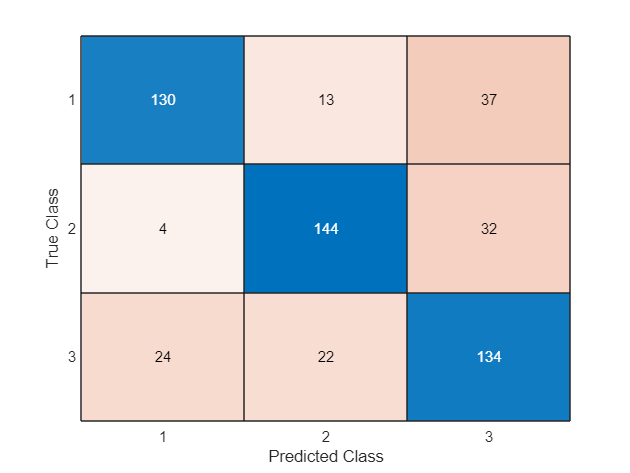

trainconchart =   ConfusionMatrixChart with properties:

    NormalizedValues: [3×3 double]
         ClassLabels: [3×1 double]

  Show all properties


trainconchart = confusionchart(y_train, y_train_predictions)

traincondata = confusionmat(y_train, y_train_predictions)

traincondata =    130    13    37
     4   144    32
    24    22   134


Calculate the Precision for Train Data

 train_rprecision = traincondata(1,1)/(traincondata(1,1)+traincondata(1,2)+traincondata(1,3));
 train_pprecision = traincondata(2,2)/(traincondata(1,2)+traincondata(2,2)+traincondata(3,2));
 train_sprecision = traincondata(3,3)/(traincondata(1,3)+traincondata(2,3)+traincondata(3,3));
 train_precision = (train_rprecision + train_pprecision + train_sprecision)/3

Calculate the Sensitivity for Train Data

 train_rsens = traincondata(1,1)/(traincondata(1,1)+traincondata(1,2)+traincondata(1,3));
 train_psens = traincondata(2,2)/(traincondata(2,1)+traincondata(2,2)+traincondata(2,3));
 train_ssens = traincondata(3,3)/(traincondata(3,1)+traincondata(3,2)+traincondata(3,3));
 train_sens = (train_rsens + train_psens + train_ssens)/3

Calculate the F1 score for Train Data

 train_rf1 = (2 * train_rprecision*train_rsens)/(train_rprecision+train_rsens);
 train_pf1 = (2 * train_pprecision*train_psens)/(train_pprecision+train_psens);
 train_sf1 = (2 * train_sprecision*train_ssens)/(train_sprecision+train_ssens);
 train_f1 = (train_rf1+train_pf1+train_sf1)/3

train_f1 = 0.7414

train_precision = 0.7289

train_sens = 0.7556

Confusion Matrix for Test Data

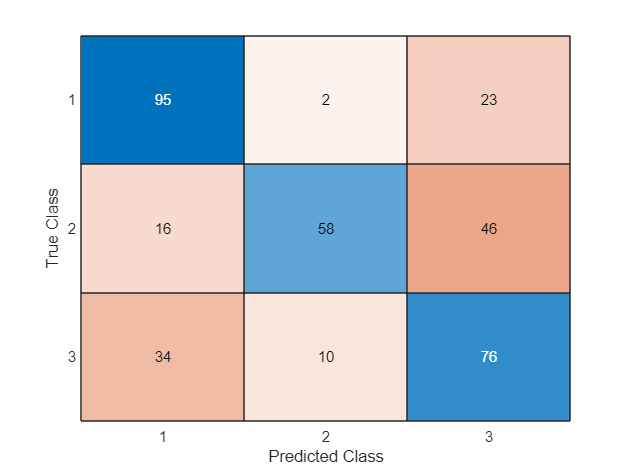

testconchart =   ConfusionMatrixChart with properties:

    NormalizedValues: [3×3 double]
         ClassLabels: [3×1 double]

  Show all properties


 testconchart = confusionchart(y_test, y_test_predictions)

testcondata = confusionmat(y_test, y_test_predictions)

testcondata =     95     2    23
    16    58    46
    34    10    76


Calculate Precision for Test Data

test_rprecision = testcondata(1,1)/(testcondata(1,1)+testcondata(1,2)+testcondata(1,3));
test_pprecision = testcondata(2,2)/(testcondata(1,2)+testcondata(2,2)+testcondata(3,2));
test_sprecision = testcondata(3,3)/(testcondata(1,3)+testcondata(2,3)+testcondata(3,3));
test_precision = (test_rprecision + test_pprecision + test_sprecision)/3


Calculate Sensitivity for Test Data

test_rsens = testcondata(1,1)/(testcondata(1,1)+testcondata(1,2)+testcondata(1,3));
test_psens = testcondata(2,2)/(testcondata(2,1)+testcondata(2,2)+testcondata(2,3));
test_ssens = testcondata(3,3)/(testcondata(3,1)+testcondata(3,2)+testcondata(3,3));
test_sens = (test_rsens + test_psens + test_ssens)/3

Calculate F1 Score for Test Data

test_rf1 = (2 * test_sprecision*test_ssens)/(test_sprecision+test_rsens);
test_pf1 = (2 * test_pprecision*test_psens)/(test_pprecision+test_psens);
test_sf1 = (2 * test_sprecision*test_ssens)/(test_sprecision+test_ssens);
test_f1 = (test_rf1+test_pf1+test_sf1)/3

test_f1 = 0.5629

test_precision = 0.7148

test_sens = 0.6361

# Helper functions

The code after this are functions that you can use and modify. By using functions to do more of the detailed work, we can better see the big picture above. And, we can better reuse the same code.

## Create X_train, y_train, X_test, and y_test. Configure train-test split here.

function [X_train, y_train, X_test, y_test] = featuresTo_X_y_train_test(filesToLoad, selected_features)


True if you have separate test data to load (or just use all the train data again), false if you want to partition it from the data.

    if size(filesToLoad,2) == 2
        isSeparateTestData = true;
    elseif size(filesToLoad,2) == 1
        isSeparateTestData = false;
    else 
        error("Wrong number of files to load.")
    end
    
    %

Load the training data. This is expecting your features to be in a table called feature_table. 

    load(filesToLoad{1})

#### If separate test data

    if isSeparateTestData   
        % Put the train data into X and y  
        X_train = feature_table(:,selected_features);
        y_train = labels;
    
    
        % If you just want to use your train data again (resubstitution), just
        % get rid of the load part and repeat the step above.
    
        % Load the test data (here, it's the same file.. so fix this)
        load(filesToLoad{2});
    
        % Put the test data into X and y  
        % You might need to change variable names here
        X_test = feature_table(:,selected_features);
        y_test = labels;
    

#### If split the train / test data from one file

    else
        % If you want to partition your data into train and test
        holdout_proportion_test = 0.25;
        try 
            % If it exists, Load a saved partition from last time (so you don't keep
            % shufflig which dat is your train and test)
            load("lastCVpartition.mat")
            disp("loading prior training-test partition")
            if cvtt.NumObservations ~= length(labels) || cvtt.TestSize/cvtt.NumObservations ~= holdout_proportion_test
                warning('Loaded cv partition does not match number of observations, delete or rename and rerun, making a temporary new one')
                
                cvtt = cvpartition(labels,"HoldOut",holdout_proportion_test); % Decimal is how much to hold out for test
            end
        catch
            cvtt = cvpartition(labels,"HoldOut",holdout_proportion_test); % Decimal is how much to hold out for test
            save("./lastCVpartition.mat","cvtt");
            disp('Making new training-test partiton')
        end
        
        % Train data
        X_train = feature_table(training(cvtt),selected_features);
        y_train = labels(training(cvtt));
    
        %Test datac
        X_test = feature_table(test(cvtt),selected_features);
        y_test = labels(test(cvtt));
    end
end



## Build a model based on data

There are various models that you can use here for 3 classes. You can add more details / parameters here.

function [theClassifier] = createClassifier(dataIn, labelsIn)
    
    % Linear discriminant analysis
    theClassifier = fitcdiscr(dataIn,labelsIn);

    % Decision tree
    % theClassifier = fitctree(dataIn,labelsIn)

    % fitcknn does k-nearest neighbors
    % theClassifier = fitcknn(dataIn,labelsIn,...
    %    "NumNeighbors",3);

end



## Calculate key metrics

You can put your other key metrics (such as F1 score) in here. You'll need to add more outputs to your function. 

function [accuracy ] = calculateMetrics(true_labels, predicted_labels)
    
    accuracy = sum(true_labels == predicted_labels) / length(true_labels);
    
end